Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x(:,1)-2).^2.*sin(12*x(:,2)-4);

xx = lhsdesign(200,2);
yy = f1(xx);

x1 = lhsdesign(1000,2);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.8);

ma = means.const(2)+means.linear([6 6])

ma =   const with properties:

         meanz: {[1×1 means.const]  [1×1 means.linear]}
        coeffs: {[2]  [6 6]}
    operations: {'+'}


a = kernels.Matern52(1,[0.2 0.5]);

a.signn = 0.5;

Z = VGP(ma,a,lhsdesign(20,2));

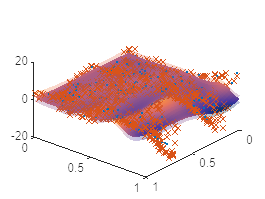

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
utils.plotSurf(Z1,2,1)
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
view(-40,-40)

tic
[Z2,LL] = Z1.train(1);
toc

Elapsed time is 3.863512 seconds.


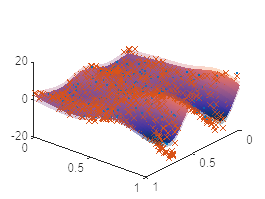

figure
hold on
utils.plotSurf(Z2,2,1)
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
view(-40,-40)


opts = bads('Defaults');
opts.Display = 'final';

for i = 1:25
    xn = bads(@(x) Z2.newXuDiff(x),rand([1 2]),[0 0],[1 1],[0 0],[1 1],[],opts);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Function value at minimum: -1.18836.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -3.94293.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -2.92028.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -5.73953.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -5.91773.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.


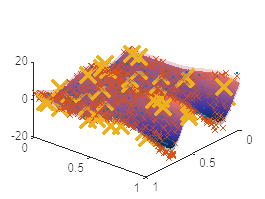


[ys,sig] = Z2.eval(xx);

figure
hold on
utils.plotSurf(Z2,2,1)
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
plot3(Z2.Xu(:,1),Z2.Xu(:,2),0*Z2.Xu(:,1),'x','MarkerSize',18,'LineWidth',3)
view(-40,-40)

tic
[Z3,LL] = Z2.train(1);
toc

Elapsed time is 9.536298 seconds.


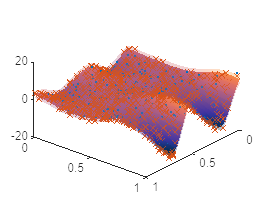


[ys,sig] = Z3.eval(xx);

figure
hold on
utils.plotSurf(Z3,2,1)
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
view(-40,-40)